% Define a known precision matrix (inverse covariance) with a known sparsity pattern
lowVariance = true

lowVariance = logical
   1


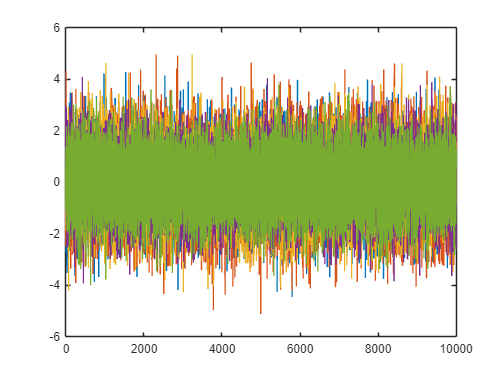

if lowVariance
    true_precision = [ 1.0, -0.5,  0.0,  0.0,  0.0;
                      -0.5,  1.0, -0.4,  0.0,  0.0;
                       0.0, -0.4,  1.0, -0.3,  0.0;
                       0.0,  0.0, -0.3,  1.0, -0.2;
                       0.0,  0.0,  0.0, -0.2,  1.0];
else
    true_precision = [ 10.0, -1.8, -1.5, -1.2, -0.9;
                  -1.8,  10.0, -1.6, -1.3, -1.0;
                  -1.5, -1.6,  10.0, -1.4, -1.1;
                  -1.2, -1.3, -1.4,  10.0, -1.2;
                  -0.9, -1.0, -1.1, -1.2,  10.0];
end

% Ensure the matrix is symmetric and positive definite
true_precision = (true_precision + true_precision') / 2;
eigvals = eig(true_precision);
if any(eigvals <= 0)
    error('Precision matrix is not positive definite');
end

% Compute the true covariance matrix as the inverse of the precision matrix
true_covariance = inv(true_precision);

% Number of samples to generate
n_samples = 10000;

% Generate data from a multivariate normal distribution
rng(0);  % Set random seed for reproducibility
data = mvnrnd(zeros(1, 5), true_covariance, n_samples);

plot(data)


% Define the sample size and reshape data into segments
% ============================================================================
sampleSize = 1000;  % Define sample size (number of time steps in each segment)
% ============================================================================
[numObservations, numVariables] = size(data);
numFullSamples = floor(numObservations / sampleSize);

% Extract only the data that fits into full samples
sampledData = data(1:numFullSamples * sampleSize, :);

% Reshape into samples with dimensions [sampleSize, numVariables, numFullSamples]
samples = reshape(sampledData, sampleSize, numVariables, numFullSamples);
size(samples)

ans =         1000           5          10



% Calculate the empirical covariance matrices for each segment
S = zeros(numVariables, numVariables, numFullSamples);  % Initialize covariance matrix storage
for t = 1:numFullSamples
    S(:, :, t) = cov(squeeze(samples(:, :, t)));  % Calculate covariance for each segment
end



S = S(:,:,1) =

    1.4330   -0.0133    0.0407   -0.0900   -0.0085
   -0.0133    1.4319    0.0745    0.0162   -0.1078
    0.0407    0.0745    1.4517    0.0085    0.0491
   -0.0900    0.0162    0.0085    1.4226   -0.0342
   -0.0085   -0.1078    0.0491   -0.0342    1.3685


S(:,:,2) =

    1.4617    0.0645    0.0113    0.0014   -0.0785
    0.0645    1.3889    0.0904    0.0370   -0.0245
    0.0113    0.0904    1.3792   -0.0416   -0.0099
    0.0014    0.0370   -0.0416    1.4413    0.0047
   -0.0785   -0.0245   -0.0099    0.0047    1.3282


S(:,:,3) =

    1.5276   -0.0480    0.0781   -0.0922    0.0245
   -0.0480    1.7249    0.0435   -0.0325    0.0171
    0.0781    0.0435    1.7343   -0.0350    0.0871
   -0.0922   -0.0325   -0.0350    1.6231   -0.1391
    0.0245    0.0171    0.0871   -0.1391    1.8333


S(:,:,4) =

    1.8043   -0.0446    0.0492   -0.0091   -0.0557
   -0.0446    1.6322    0.0714   -0.0147   -0.0026
    0.0492    0.0714    1.8152    0.0231    0.0116
   -0.0091   -0.0147    

% Initialize ADMM parameters
rho = 1;                       % Initial rho value
tau_increase = 1.1;            % Factor to increase rho
tau_decrease = 1.1;            % Factor to decrease rho
max_rho = 10;                  % Maximum rho value
min_rho = 0.01;                % Minimum rho value


lambda = 0.1

lambda = 0.1000

beta = 1

beta = 1

penalty_type = 'l1'

penalty_type = 'l1'


max_iter = 1

max_iter = 1

tol = 1e-4

tol = 1.0000e-04



% Parameters:
% S - Empirical covariance matrices for each time point (3D array)
% n - Number of observations
% rho - ADMM penalty parameter
% lambda - Regularization parameter for sparsity
% beta - Regularization parameter for temporal consistency
% penalty_type - Type of penalty ('l1', 'l2', 'laplacian', 'l_inf')
% max_iter - Maximum number of ADMM iterations
% tol - Convergence tolerance for residuals

% Initialize variables
[p, ~, T] = size(S);        % p: dimension of each matrix, T: number of time points
Z0 = zeros(p, p, T);        % Initialize Z0 (sparsity) 1 - T 
Z1 = zeros(p, p, T);        % Initialize Z1 (temporal consistency) 1 - T-1
Z2 = zeros(p, p, T);        % Initialize Z2 (temporal consistency) 2 - T

U0 = zeros(p, p, T);        % Initialize U0 (dual variable for sparsity) 1 - T 
U1 = zeros(p, p, T);        % Initialize U1 (dual variable for Z1) 1 - T-1
U2 = zeros(p, p, T);        % Initialize U2 (dual variable for Z2) 2 - T

% ADMM iteration loop
for k = 1:max_iter
    Z0_prev = Z0;
    Z1_prev = Z1;
    Z2_prev = Z2;

    % Step (a): Update Theta using the theta_update function
    Theta = theta_update(Z0, Z1, Z2, U0, U1, U2, S, numFullSamples, rho);

    % Step (b): Update Z using the z_update function
    [Z0,Z1,Z2] = z_update(Theta, U0, U1, U2, lambda, beta, rho, penalty_type);

    % Step (c): Update dual variables U using the u_update function
    [U0, U1, U2] = u_update(U0, U1, U2, Theta, Z0, Z1, Z2);
    

    primal_residual = 0;
    for t = 1:T
        primal_residual = primal_residual + norm(Theta(:,:,t) - Z0(:,:,t), 'fro')^2;
    end
    for t = 2:T
        primal_residual = primal_residual + norm(Theta(:,:,t-1) - Z1(:,:,t-1), 'fro')^2 + norm(Theta(:,:,t) - Z2(:,:,t), 'fro')^2;
    end
    primal_residual = sqrt(primal_residual);
        

    dual_residual = 0;
    for t = 1:T
        dual_residual = dual_residual + norm(rho * (Z0(:,:,t) - Z0_prev(:,:,t)), 'fro')^2;
    end
    for t = 2:T
        dual_residual = dual_residual + norm(rho * (Z1(:,:,t-1) - Z1_prev(:,:,t-1)), 'fro')^2 + norm(rho * (Z2(:,:,t) - Z2_prev(:,:,t)), 'fro')^2;
    end
    dual_residual = sqrt(dual_residual);


    % Adaptive adjustment of rho based on residuals
    if primal_residual > 10 * dual_residual
        % Increase rho if primal residual is much larger
        rho = min(rho * tau_increase, max_rho);
    elseif dual_residual > 10 * primal_residual
        % Decrease rho if dual residual is much larger
        rho = max(rho / tau_decrease, min_rho);
    end
    

    % Check convergence
    if primal_residual < tol && dual_residual < tol
        disp(['Converged at iteration ', num2str(k)]);
        break;
    end

    % Display progress every 10 iterations
    if mod(k, 10) == 0
        fprintf('Iteration %d: Primal Residual = %.6f, Dual Residual = %.6f\n', k, primal_residual, dual_residual);
    end
end

A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0




% If maximum iterations are reached
if k == max_iter
    disp('Reached maximum iterations without full convergence');
end

Reached maximum iterations without full convergence


% Cosntraint to enforce PSD, not required
enforce_psd = false;

% Initial guess: use only upper triangular elements
Theta0t = repmat(eye(size(S,1)), 1, 1, numFullSamples); 
% Call the custom Graphical Lasso fitting function with Lasso penalty
Theta_estimated_TVGL_TP= fitTimeVaryingGraphicalLassoSmoothing(Theta0t, S, lambda, beta, numFullSamples, enforce_psd);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Display the result
disp('TVGL with Transition Penalty: Optimal Precision Matrix (Theta):');

TVGL with Transition Penalty: Optimal Precision Matrix (Theta):


disp(Theta_estimated_TVGL_TP);


(:,:,1) =

    0.7013    0.0076   -0.0205    0.0446    0.0068
    0.0076    0.7048   -0.0383   -0.0059    0.0568
   -0.0205   -0.0383    0.6924   -0.0057   -0.0281
    0.0446   -0.0059   -0.0057    0.7063    0.0177
    0.0068    0.0568   -0.0281    0.0177    0.7367


(:,:,2) =

    0.6877   -0.0310   -0.0033   -0.0001    0.0401
   -0.0310    0.7253   -0.0478   -0.0200    0.0112
   -0.0033   -0.0478    0.7289    0.0223    0.0043
   -0.0001   -0.0200    0.0223    0.6950   -0.0027
    0.0401    0.0112    0.0043   -0.0027    0.7555


(:,:,3) =

    0.6591    0.0198   -0.0292    0.0368   -0.0048
    0.0198    0.5810   -0.0150    0.0121   -0.0040
   -0.0292   -0.0150    0.5798    0.0083   -0.0264
    0.0368    0.0121    0.0083    0.6226    0.0462
   -0.0048   -0.0040   -0.0264    0.0462    0.5503


(:,:,4) =

    0.5557    0.0159   -0.0159    0.0036    0.0186
    0.0159    0.6142   -0.0247    0.0054    0.0018
   -0.0159   -0.0247    0.5524   -0.0074   -0.0046
    0.0036    0.0054   -0.0074 

X1 = randn(5,5)

X1 =     0.2239    1.6718    1.2222    0.9089    0.9945
   -1.5177    0.3355    0.1403   -0.6624    0.0203
   -1.3277    2.1275    0.1344    0.3248   -0.7867
   -0.1389    0.5309    1.0905    0.2770   -0.0999
   -0.2400   -0.6128   -0.3397   -1.2154    0.5130


X = (X1 + X1')/2

X =     0.2239    0.0771   -0.0528    0.3850    0.3773
    0.0771    0.3355    1.1339   -0.0657   -0.2962
   -0.0528    1.1339    0.1344    0.7077   -0.5632
    0.3850   -0.0657    0.7077    0.2770   -0.6576
    0.3773   -0.2962   -0.5632   -0.6576    0.5130



X + 4*eta*eye(5,5)

ans =     4.2239    0.0771   -0.0528    0.3850    0.3773
    0.0771    4.3355    1.1339   -0.0657   -0.2962
   -0.0528    1.1339    4.1344    0.7077   -0.5632
    0.3850   -0.0657    0.7077    4.2770   -0.6576
    0.3773   -0.2962   -0.5632   -0.6576    4.5130



[Q,D] = eig(X)

Q =     0.1982   -0.5107    0.8229   -0.1503   -0.0144
   -0.5485   -0.1882    0.1418    0.6470    0.4744
    0.6765    0.3601    0.1107    0.2185    0.5938
   -0.4414    0.4356    0.2726   -0.6093    0.4121
   -0.0860    0.6200    0.4650    0.3738   -0.5023


D =    -1.1904         0         0         0         0
         0   -0.4970         0         0         0
         0         0    0.5708         0         0
         0         0         0    0.5914         0
         0         0         0         0    2.0091



eye(size(D))

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1




sign(X1)

ans =      1     1     1     1     1
    -1     1     1    -1     1
    -1     1     1     1    -1
    -1     1     1     1    -1
    -1    -1    -1    -1     1
